# Calcualtion of Inter Hamming Distance for all devices without AuNPs

 (C) 2021, Juan Esteban Villegas, NYUAD

For this test, we compare all combinations of the response of the same device type and compute the al HD metrics for each design. We then generate plots of  Hamming Distance combining all resulting HDs.

## Read data

First extract the data from the H5 file. 

clear('files', 'resultsAu0_dev1', 'resultsAu0_dev2', 'resultsAu0_dev3');
folder = '..\Datasets\';
files{1} = 'AllDevices_Au0_Chips02_01_TE_user01_1504.h5';
files{2} = 'AllDevices_Au0_Chips02_01_TM_user01_1504.h5';

idx = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    data{idx} = struct.project.measurements; 
    idx = idx+1;
end

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We compare only the drop ports in the design 3 type of devices.
dev_ind   = 13:24;    % Index opf the oimetrest devices ()  
dev_port = ones(1,length(dev_ind)); dev_port(9:12) = 2; %

ind_file = 1; clear dataset;
for file = files
    meas = data{ind_file} ;
    response=[];
    for i = 1:length(dev_ind)
        idx = findinproject(dev_ind(i),dev_port(i),meas);
        extract_meas = meas(idx); 
        if (iscell(extract_meas)), extract_meas = extract_meas{1};end
        m = extract_meas.spectra;
        response(:,i) = m(:,2);
        lambda = m(:,1);
    end
    dataset{ind_file} = response;
    ind_file = ind_file+1;
end

We now compute  the HD metrics for each file, the shifted datasets are computed inside of the function MultiHD

L=0.15; clear('resultsAu0_dev1','resultsAu0_dev2','resultsAu0_dev3','avg','sigma')
for file_ind = 1:2
    resultsAu0_dev1{file_ind} = multi_HD(lambda, dataset{file_ind}(:,1:4 ), L);
    resultsAu0_dev2{file_ind} = multi_HD(lambda, dataset{file_ind}(:,5:8 ), L);
    resultsAu0_dev3{file_ind} = multi_HD(lambda, dataset{file_ind}(:,9:12), L);
    
    avg{file_ind} = [   mean(resultsAu0_dev1{file_ind}.mean{1}) ; ...
                        mean(resultsAu0_dev2{file_ind}.mean{1}); ...
                        mean(resultsAu0_dev3{file_ind}.mean{1})];
    
    sigma{file_ind} = [ mean(resultsAu0_dev1{file_ind}.mean{2}) ; ...
                        mean(resultsAu0_dev2{file_ind}.mean{2}); ...
                        mean(resultsAu0_dev3{file_ind}.mean{2})];
end

disp("Average Intra HD Au0 for TE0")

Average Intra HD Au0 for TE0


display_results(avg{1} , sigma{1});

242.0± 25.7 (223.2± 22.9) 	200.4± 25.0 (124.0± 20.0) 	499.2± 29.2 (370.9± 21.7) 	 
0.060± 0.018 (0.051± 0.017) 	0.051± 0.017 (0.016± 0.010) 	0.376± 0.040 (0.242± 0.035) 	 
0.209± 0.032 (0.198± 0.031) 	0.141± 0.029 (0.086± 0.022) 	0.355± 0.040 (0.286± 0.037) 	 



disp("Average Intra HD Au0 for TM0")

Average Intra HD Au0 for TM0


display_results(avg{2} , sigma{2});

436.9± 39.3 (437.2± 38.6) 	372.0± 27.7 (352.1± 28.9) 	360.1± 30.5 (213.9± 23.4) 	 
0.253± 0.036 (0.255± 0.035) 	0.205± 0.033 (0.172± 0.031) 	0.195± 0.030 (0.054± 0.018) 	 
0.315± 0.039 (0.314± 0.039) 	0.303± 0.037 (0.277± 0.036) 	0.271± 0.036 (0.160± 0.030) 	 


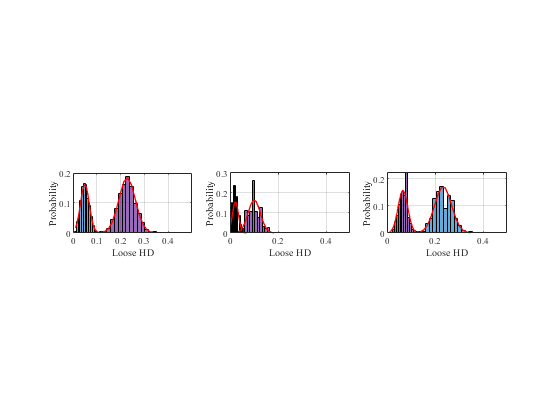

%Plot for LHD for both TE and TM polarization states

    h = figure(); clf, hold off; haxis = [0,0.5];
    device = 4; metric = 3; %Metric: Loose HD
    subplot(1,3,1), 
        h = plotHD(resultsAu0_dev1{1}.HDData_s{metric}(:,device),'Loose HD',haxis);
        grid on; hold on;
        h = plotHD(resultsAu0_dev1{2}.HDData_s{metric}(:,device),'Loose HD',haxis,'#57068c'); grid on;
    
    subplot(1,3,2), 
        h = plotHD(resultsAu0_dev2{1}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
        hold on;
        h = plotHD(resultsAu0_dev2{2}.HDData_s{metric}(:,device),'Loose HD',haxis,'#57068c'); grid on; 
    
    subplot(1,3,3),
        h = plotHD(resultsAu0_dev3{1}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
        hold on;
        h = plotHD(resultsAu0_dev3{2}.HDData_s{metric}(:,device),'Loose HD',haxis,'#57068c'); grid on;